# Avoid Obstacles Using Reinforcement Learning for Mobile Robots

This example uses Deep Deterministic Policy Gradient (DDPG) based reinforcement learning to develop a strategy for a mobile robot to avoid obstacles. For a brief summary of the DDPG algorithm, see [Deep Deterministic Policy Gradient Agents](docid:rl_ug#mw_66c8fe60-f58e-4bdb-904a-21d442f0a879). 

This example scenario trains a mobile robot to avoid obstacles given range sensor readings that detect obstacles in the map. The objective of the reinforcement learning algorithm is to learn what controls (linear and angular velocity), the robot should use to avoid colliding into obstacles. This example uses an occupancy map of a known environment to generate range sensor readings, detect obstacles, and check collisions the robot may make. The range sensor readings are the observations for the DDPG agent, and the linear and angular velocity controls are the action.

이 예제에서는 DDPG(Deep Deterministic Policy Gradient) 기반 강화 학습을 사용하여 장애물을 피하기 위한 모바일 로봇의 전략을 개발합니다. DDPG 알고리즘에 대한 간략한 요약은 Deep Deterministic Policy Gradient Agents를 참조하십시오. 이 예제 시나리오는 지도에서 장애물을 감지하는 범위 센서 판독값이 주어지면 장애물을 피하도록 모바일 로봇을 훈련시킵니다. 강화 학습 알고리즘의 목적은 로봇이 장애물과의 충돌을 피하기 위해 사용해야 하는 제어(선형 및 각속도)를 배우는 것입니다. 이 예에서는 알려진 환경의 점유 맵을 사용하여 범위 센서 판독값을 생성하고, 장애물을 감지하고, 로봇이 만들 수 있는 충돌을 확인합니다. 범위 센서 판독값은 DDPG 에이전트에 대한 관찰값이고 선형 및 각속도 제어는 작업입니다

### Load Map

Load a map matrix, `simpleMap`, that represents the environment for the robot.

load exampleMaps simpleMap 
load exampleHelperOfficeAreaMap office_area_map
mapMatrix = simpleMap;
mapScale = 1;

### Range Sensor Parameters

Next, set up a `rangeSensor` object which simulates a noisy range sensor. The range sensor readings are considered observations by the agent. Define the angular positions of the range readings, the max range, and the noise parameters.

다음으로, 노이즈가 있는 범위 센서를 시뮬레이션하는 rangeSensor 객체를 설정합니다. 범위 센서 판독값은 상담원이 관찰한 것으로 간주됩니다. 범위 판독값의 각도 위치, 최대 범위 및 노이즈 매개변수를 정의합니다.

scanAngles = [-3*pi/8:pi/8:3*pi/8];
maxRange = 12;
lidarNoiseVariance = 0.1^2;
lidarNoiseSeeds = randi(intmax,size(scanAngles));

### Robot Parameters

The action of the agent is a two-dimensional vector $a = [v , \omega] $ where $v$ and $\omega$ are the linear and angular velocities of our robot. The DDPG agent uses normalized inputs for both the angular and linear velocities, meaning the actions of the agent are a scalar between -1 and 1, which is multiplied by the `maxLinSpeed` and `maxAngSpeed` parameters to get the actual control. Specify this maximum linear and angular velocity.

에이전트의 동작은 2차원 벡터이며 여기서 및 는 로봇의 선형 및 각속도입니다. DDPG 에이전트는 각 및 선형 속도 모두에 대해 정규화된 입력을 사용합니다. 즉, 에이전트의 동작은 -1과 1 사이의 스칼라이며, 실제 제어를 얻기 위해 maxLinSpeed ��및 maxAngSpeed ��매개변수를 곱합니다. 이 최대 선형 및 각속도를 지정합니다.

Also, specify the initial position of the robot as `[x y theta]`.

% Max speed parameters
maxLinSpeed = 0.3;
maxAngSpeed = 0.3;

% Initial pose of the robot
initX = 17;
initY = 15;
initTheta = pi/2;

### Show Map and Robot Positions

To visualize the actions of the robot, create a figure. Start by showing the occupancy map and plot the initial position of the robot.

로봇의 동작을 시각화하려면 그림을 만드십시오. 점유 맵을 표시하여 시작하고 로봇의 초기 위치를 플로팅합니다.

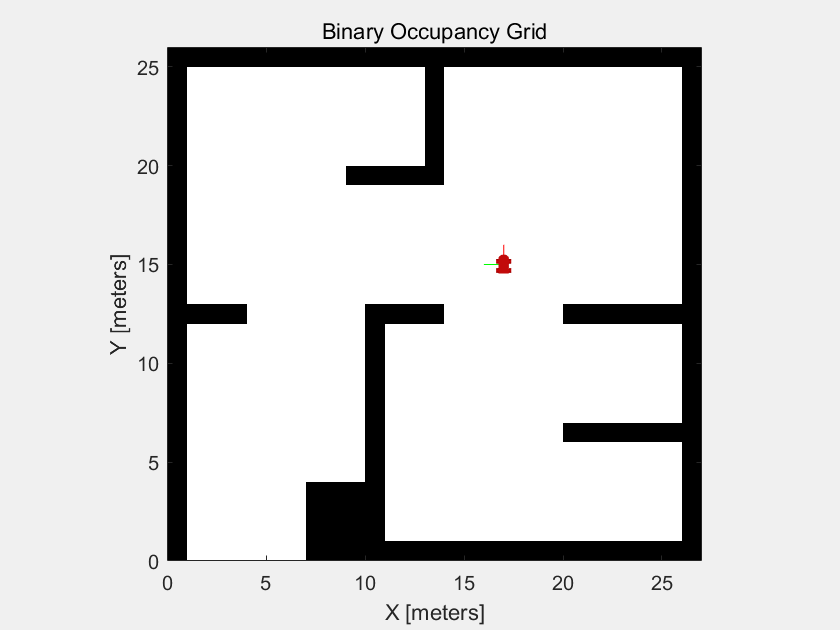

fig = figure("Name","simpleMap");
set(fig, "Visible","on");
ax = axes(fig);

show(binaryOccupancyMap(mapMatrix),"Parent",ax);
hold on
plotTransforms([initX,initY,0],eul2quat([initTheta,0,0]),"MeshFilePath","groundvehicle.stl","View","2D");
light;
hold off

### Environment Interface

Create an environment model that takes the action, and gives the observation and reward signals. Specify the provided example model name, ex`ampleHelperAvoidObstaclesMobileRobot`, the simulation time parameters, and the agent block name.

조치를 취하고 관찰 및 보상 신호를 제공하는 환경 모델을 만듭니다. 제공된 예제 모델 이름, exampleHelperAvoidObstaclesMobileRobot, 시뮬레이션 시간 매개변수 및 에이전트 블록 이름을 지정합니다.

mdl = "exampleHelperAvoidObstaclesMobileRobot";
Tfinal = 100;
sampleTime = 0.1;

agentBlk = mdl + "/Agent";

Open the model.

open_system(mdl)

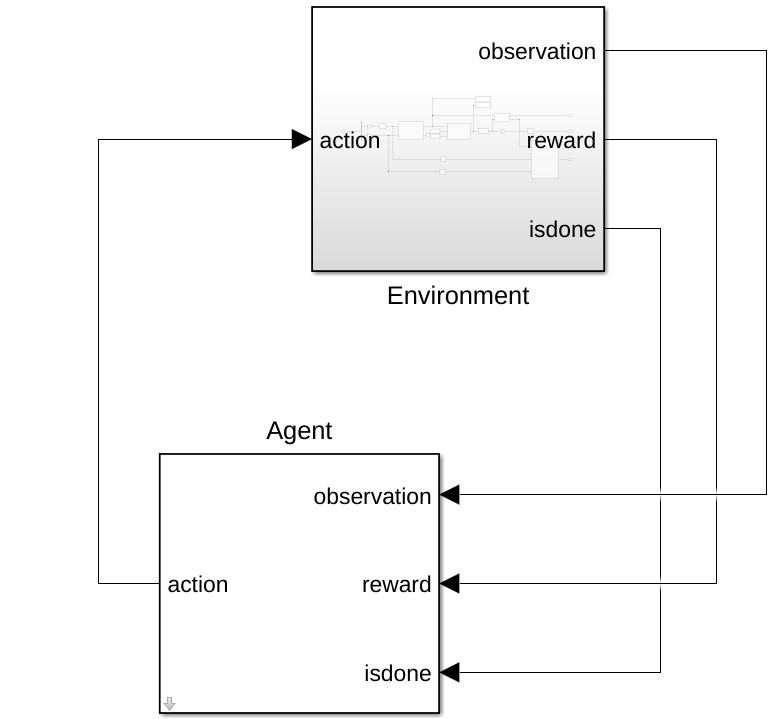

The model contains the `Environment` and `Agent` blocks. The `Agent` block is not defined yet.

Inside the `Environment` Subsystem block, you should see a model for simulating the robot and sensor data. The subsystem takes in the action, generates the observation signal based on the range sensor readings, and calculates the reward based on the distance from obstacles, and the effort of the action commands.

모델에는 환경 및 에이전트 블록이 포함됩니다. 에이전트 블록은 아직 정의되지 않았습니다. 환경 하위 시스템 블록 내에서 로봇 및 센서 데이터를 시뮬레이션하기 위한 모델이 표시되어야 합니다. 하위 시스템은 조치를 취하고 거리 센서 판독값을 기반으로 관찰 신호를 생성하고 장애물과의 거리 및 조치 명령의 노력에 따라 보상을 계산합니다.

open_system(mdl + "/Environment")

Define observation parameters, `obsInfo`, using the `rlNumericSpec` object and giving the lower and upper limit for the range readings with enough elements for each angular position in the range sensor.

rlNumericSpec 개체를 사용하여 관찰 매개변수 obsInfo를 정의하고 범위 센서의 각 각도 위치에 대한 충분한 요소로 범위 판독값에 대한 하한 및 상한을 제공합니다.

obsInfo = rlNumericSpec([numel(scanAngles) 1],...
    "LowerLimit",zeros(numel(scanAngles),1),...
    "UpperLimit",ones(numel(scanAngles),1)*maxRange);
numObservations = obsInfo.Dimension(1);

Define action parameters, `actInfo`. The action is the control command vector, $a = [v , \omega] $, normalized to $[-1, 1]$.

조치 매개변수 actInfo를 정의하십시오. 동작은 로 정규화된 제어 명령 벡터 입니다.

numActions = 2;
actInfo = rlNumericSpec([numActions 1],...
    "LowerLimit",-1,...
    "UpperLimit",1);

Build the environment interface object using [`rlSimulinkEnv`](docid:rl_ref.mw_12cc40dc-3191-4a23-af71-1625696c1a14). Specify the model, agent block name, observation parameters, and action parameters. Set the reset function for the simulation using `exampleHelperRLAvoidObstaclesResetFcn`. This function restarts the simulation by placing the robot in a new random location to begin avoiding obstacles. 

rlSimulinkEnv를 사용하여 환경 인터페이스 개체를 빌드합니다. 모델, 에이전트 블록 이름, 관찰 매개변수 및 작업 매개변수를 지정합니다. exampleHelperRLAvoidObstaclesResetFcn을 사용하여 시뮬레이션에 대한 재설정 기능을 설정합니다. 이 기능은 로봇을 새로운 임의의 위치에 배치하여 장애물을 피하기 시작함으로써 시뮬레이션을 다시 시작합니다.

env = rlSimulinkEnv(mdl,agentBlk,obsInfo,actInfo);
env.ResetFcn = @(in)exampleHelperRLAvoidObstaclesResetFcn(in,scanAngles,maxRange,mapMatrix);
env.UseFastRestart = "Off";

For another example that sets up a Simulink® environment for training, see [Create Simulink Environment and Train Agent](docid:rl_ug.mw_873bd3fc-b713-4e71-b776-9758762d592c).

## DDPG Agent

A DDPG agent approximates the long-term reward given observations and actions using a critic value function representation. To create the critic, first create a deep neural network with two inputs, the observation and action, and one output. For more information on creating a deep neural network value function representation, see [Create Policy and Value Function Representations](docid:rl_ug#mw_2c7e8669-1e91-4d42-afa6-674009a08004).

DDPG 에이전트는 비평가 가치 함수 표현을 사용하여 관찰 및 행동이 주어지면 장기 보상을 근사화합니다. 비평가를 생성하려면 먼저 두 개의 입력(관찰 및 행동)과 하나의 출력으로 심층 신경망을 생성합니다. 심층 신경망 가치 함수 표현 생성에 대한 자세한 내용은 정책 및 가치 함수 표현 생성을 참조하십시오.

statePath = [
    featureInputLayer(numObservations, "Normalization","none","Name","State")
    fullyConnectedLayer(50,"Name","CriticStateFC1")
    reluLayer("Name","CriticRelu1")
    fullyConnectedLayer(25,"Name","CriticStateFC2")];
actionPath = [
    featureInputLayer(numActions,"Normalization","none","Name","Action")
    fullyConnectedLayer(25,"Name","CriticActionFC1")];
commonPath = [
    additionLayer(2,"Name","add")
    reluLayer("Name","CriticCommonRelu")
    fullyConnectedLayer(1,"Name","CriticOutput")];

criticNetwork = layerGraph();
criticNetwork = addLayers(criticNetwork,statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);
criticNetwork = connectLayers(criticNetwork,"CriticStateFC2","add/in1");
criticNetwork = connectLayers(criticNetwork,"CriticActionFC1","add/in2");
criticNetwork = dlnetwork(criticNetwork);

Next, specify options for the critic optimizer using `rlOptimizerOptions`.

Finally, create the critic representation using the specified deep neural network and options. You must also specify the action and observation specifications for the critic, which you obtain from the environment interface. For more information, see [rlQValueFunction](docid:rl_ref#mw_e6e7abac-0a33-423b-8473-1409879db701).

다음으로 rlOptimizerOptions를 사용하여 비평가 최적화 프로그램에 대한 옵션을 지정합니다. 마지막으로 지정된 심층 신경망 및 옵션을 사용하여 비평가 표현을 만듭니다. 또한 환경 인터페이스에서 얻은 비평가에 대한 조치 및 관찰 사양을 지정해야 합니다. 자세한 내용은 rlQValueFunction을 참조하세요.

criticOptions = rlOptimizerOptions("LearnRate",1e-3,"L2RegularizationFactor",1e-4,"GradientThreshold",1);
critic = rlQValueFunction(criticNetwork,obsInfo,actInfo,"ObservationInputNames","State","ActionInputNames","Action");

A DDPG agent decides which action to take given observations using an actor representation. To create the actor, first create a deep neural network with one input, the observation, and one output, the action.

Finally, construct the actor in a similar manner as the critic. For more information, see [`rlContinuousDeterministicActor`](docid:rl_ref#mw_c2909424-90f4-4a52-803b-73310483e6c3).

DDPG 에이전트는 행위자 표현을 사용하여 주어진 관찰을 수행할 조치를 결정합니다. 액터를 생성하려면 먼저 하나의 입력이 관찰이고 하나의 출력이 동작인 심층 신경망을 만듭니다. 마지막으로 비평가와 유사한 방식으로 배우를 구성합니다. 자세한 내용은 rlContinuousDeterministicActor를 참조하세요.

actorNetwork = [
    featureInputLayer(numObservations,"Normalization","none","Name","State")
    fullyConnectedLayer(50,"Name","actorFC1")
    reluLayer("Name","actorReLU1")
    fullyConnectedLayer(50, "Name","actorFC2")
    reluLayer("Name","actorReLU2")
    fullyConnectedLayer(2, "Name","actorFC3")
    tanhLayer("Name","Action")];
actorNetwork = dlnetwork(actorNetwork);

actorOptions = rlOptimizerOptions("LearnRate",1e-4,"L2RegularizationFactor",1e-4,"GradientThreshold",1);
actor = rlContinuousDeterministicActor(actorNetwork,obsInfo,actInfo);

### Create DDPG agent object

Specify the agent options.

에이전트 옵션을 지정합니다.

agentOpts = rlDDPGAgentOptions(...
    "SampleTime",sampleTime,...
    "ActorOptimizerOptions",actorOptions,...
    "CriticOptimizerOptions",criticOptions,...
    "DiscountFactor",0.995, ...
    "MiniBatchSize",128, ...
    "ExperienceBufferLength",1e6); 

agentOpts.NoiseOptions.Variance = 0.1;
agentOpts.NoiseOptions.VarianceDecayRate = 1e-5;

Create the `rlDDPGAgent` object. The `obstacleAvoidanceAgent` variable is used in the model for the `Agent` block.

rlDDPGAgent 개체를 만듭니다. 장애물AvoidanceAgent 변수는 에이전트 블록에 대한 모델에서 사용됩니다.

obstacleAvoidanceAgent = rlDDPGAgent(actor,critic,agentOpts);
open_system(mdl + "/Agent")

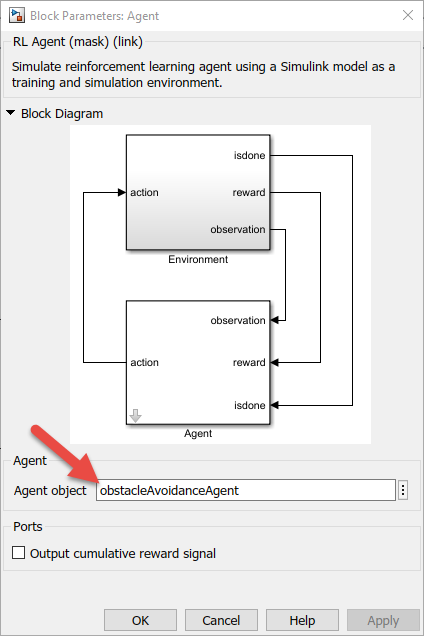

## Reward

The reward function for the agent is modeled as shown.

에이전트에 대한 보상 기능은 다음과 같이 모델링됩니다.

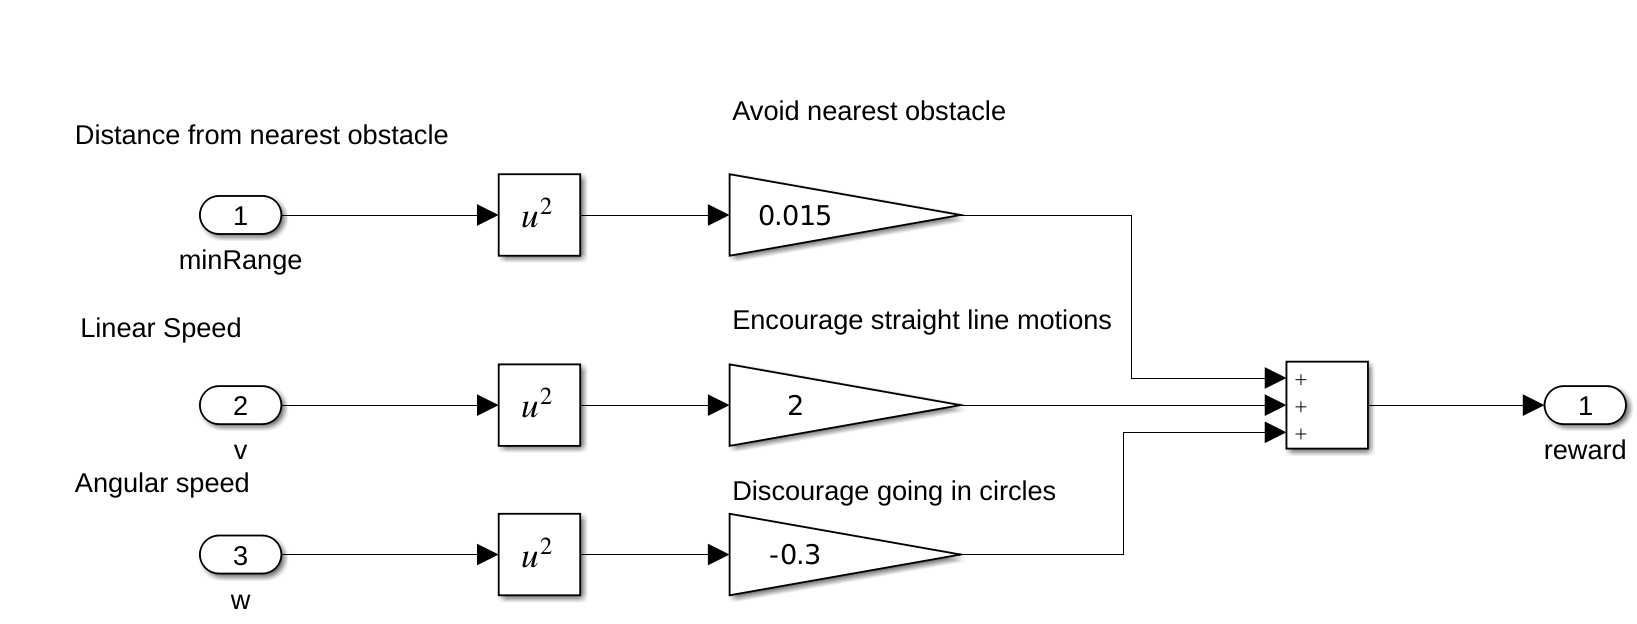

The agent is rewarded to avoid the nearest obstacle, which minimizes the worst-case scenario. Additionally, the agent is given a positive reward for higher linear speeds, and is given a negative reward for higher angular speeds. This rewarding strategy discourages the agent's behavior of going in circles. Tuning your rewards is key to properly training an agent, so your rewards vary depending on your application.

에이전트는 최악의 시나리오를 최소화하는 가장 가까운 장애물을 피하기 위해 보상을 받습니다. 또한 에이전트는 더 높은 선형 속도에 대해 긍정적인 보상을 받고 더 높은 각속도에 대해 부정적인 보상을 받습니다. 이 보상 전략은 상담원의 서클 활동을 억제합니다. 보상을 조정하는 것은 에이전트를 적절하게 교육하는 데 중요하므로 보상은 애플리케이션에 따라 다릅니다.

## Train Agent

To train the agent, first specify the training options. For this example, use the following options:

에이전트를 훈련시키려면 먼저 훈련 옵션을 지정하십시오. 이 예에서는 다음 옵션을 사용합니다

- Train for at most `10000` episodes, with each episode lasting at most `maxSteps` time steps.

- Display the training progress in the Episode Manager dialog box (set the `Plots` option) and enable the command line display (set the `Verbose` option to true).

- Stop training when the agent receives an average cumulative reward greater than 400 over fifty consecutive episodes.

최대 10000개의 에피소드에 대해 훈련하고 각 에피소드는 최대 maxSteps 시간 간격으로 지속됩니다.

에피소드 관리자 대화 상자에 교육 진행 상황을 표시하고(플롯 옵션 설정) 명령줄 표시를 활성화합니다(자세한 정보 옵션을 true로 설정). 

에이전트가 연속 50회에 걸쳐 400보다 큰 평균 누적 보상을 받으면 교육을 중지합니다.

For more information, see [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0).

maxEpisodes = 10000;
maxSteps = ceil(Tfinal/sampleTime);
trainOpts = rlTrainingOptions(...
    "MaxEpisodes",maxEpisodes, ...
    "MaxStepsPerEpisode",maxSteps, ...
    "ScoreAveragingWindowLength",50, ...
    "StopTrainingCriteria","AverageReward", ...
    "StopTrainingValue",400, ...
    "Verbose", true, ...
    "Plots","training-progress");

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. Training is a computationally-intensive process that takes several minutes to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

train 함수를 사용하여 에이전트를 훈련시킵니다. 훈련은 완료하는 데 몇 분이 걸리는 계산 집약적인 프로세스입니다. 이 예제를 실행하는 동안 시간을 ��절약하려면 doTraining을 false로 설정하여 사전 훈련된 에이전트를 로드하십시오. 에이전트를 직접 훈련시키려면 doTraining을 true로 설정하십시오.

doTraining = false; % Toggle this to true for training. 

if doTraining
    % Train the agent.
    trainingStats = train(obstacleAvoidanceAgent,env,trainOpts);
else
    % Load pretrained agent for the example.
    load exampleHelperAvoidObstaclesAgent obstacleAvoidanceAgent
end

The **Reinforcement Learning Episode Manager** can be used to track episode-wise training progress. As the episode number increases, you want to see an increase in the reward value.

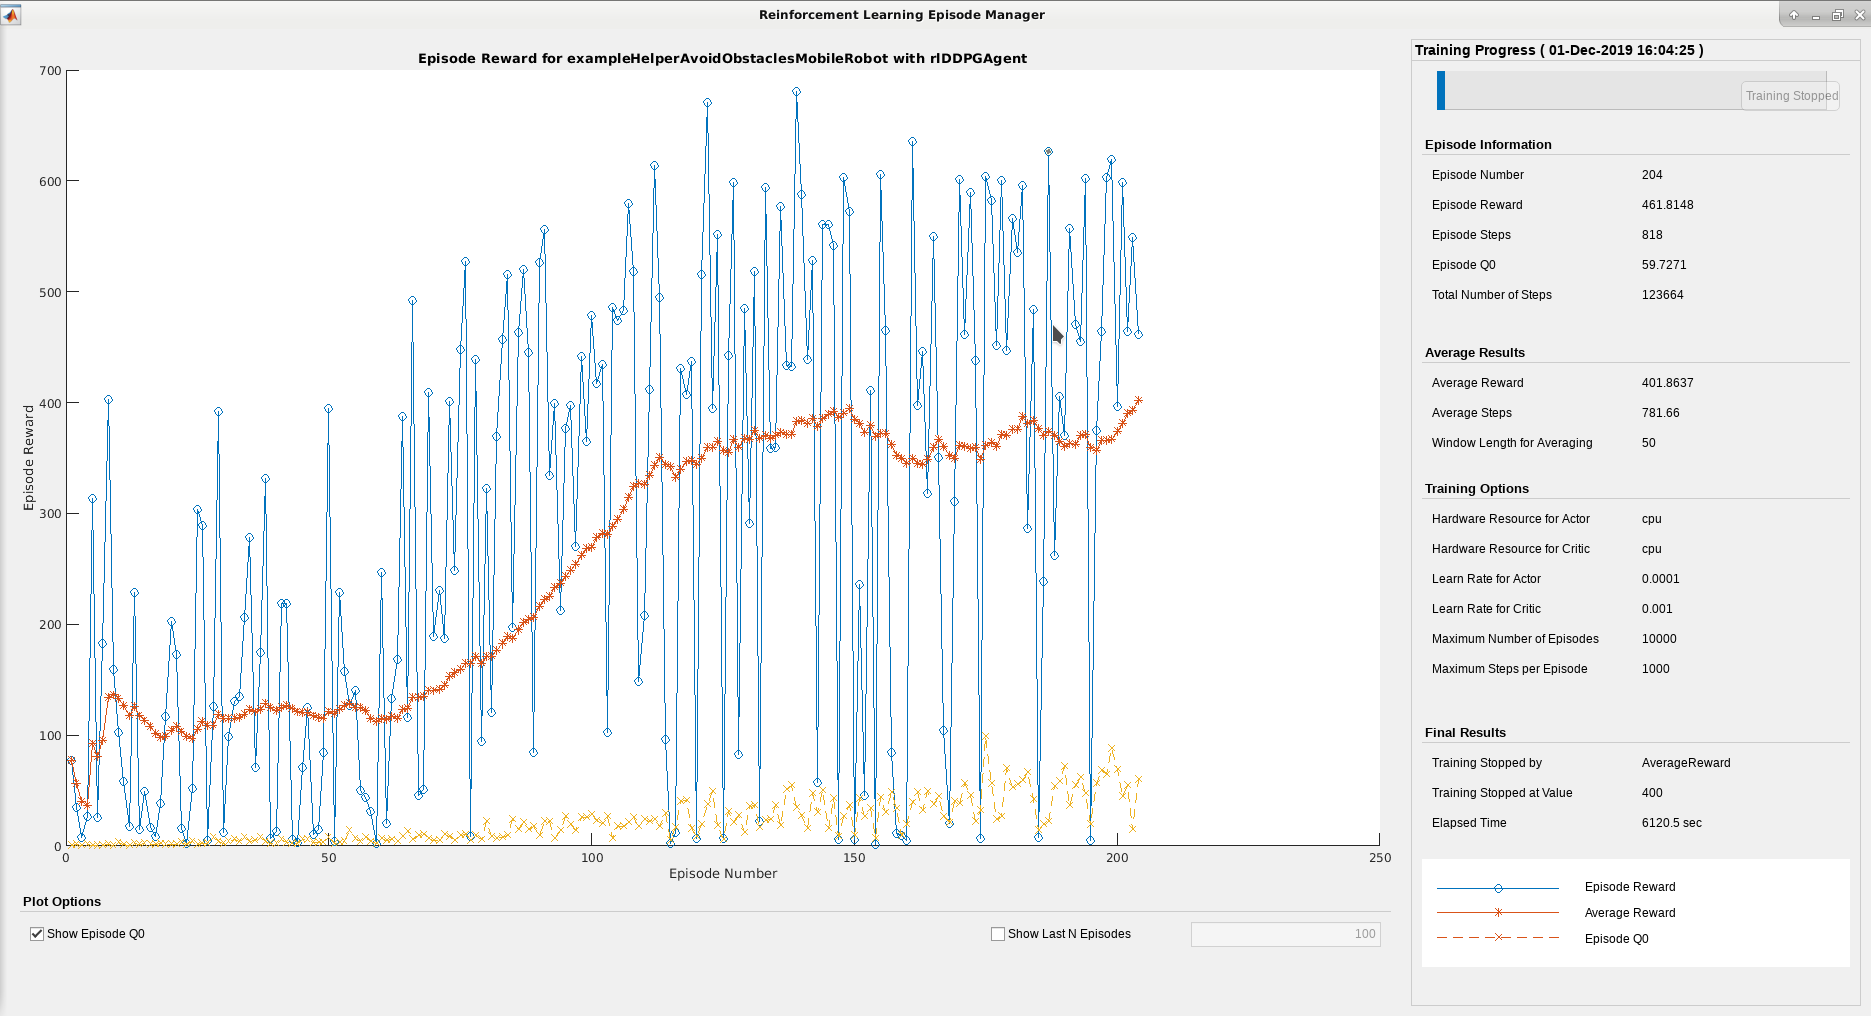

## Simulate

Use the trained agent to simulate the robot driving in the map and avoiding obstacles.

훈련된 에이전트를 사용하여 지도에서 운전하고 장애물을 피하는 로봇을 시뮬레이션하십시오.

out = sim("exampleHelperAvoidObstaclesMobileRobot.slx");

## Visualize

To visualize the simulation of the robot driving around the environment with range sensor readings, use the helper, `exampleHelperAvoidObstaclesPosePlot`.

범위 센서 판독값을 사용하여 환경 주위를 운전하는 로봇의 시뮬레이션을 시각화하려면 도우미 exampleHelperAvoidObstaclesPosePlot을 사용하십시오.

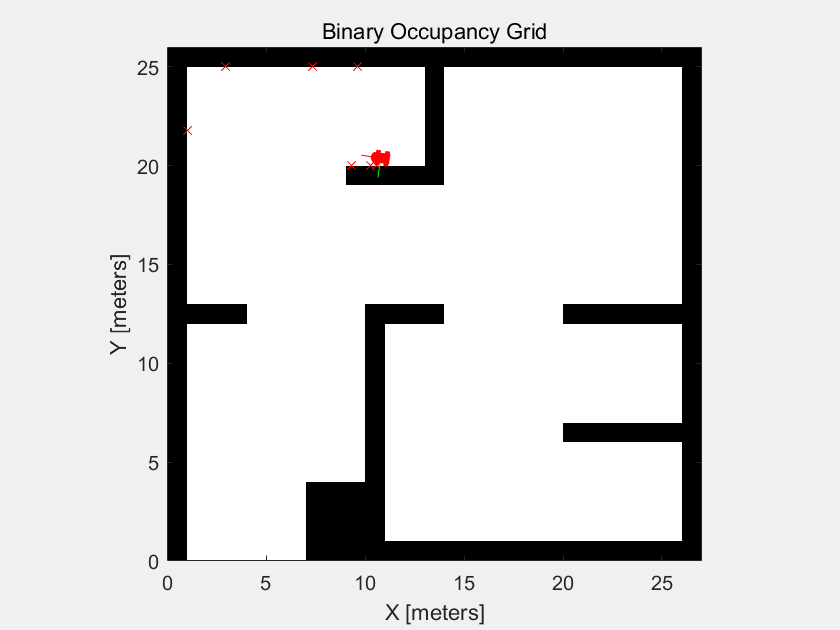

for i = 1:5:size(out.range,3)
    u = out.pose(i,:);
    r = out.range(:,:,i);
    exampleHelperAvoidObstaclesPosePlot(u,mapMatrix,mapScale,r,scanAngles,ax);
end

## Extensibility

You can now use this agent to simulate driving in a different map. Another map generated from lidar scans of an office environment is used with the same trained model. This map represents a more realistic scenario to apply the trained model after training.

이제 이 에이전트를 사용하여 다른 지도에서 운전을 시뮬레이션할 수 있습니다. 사무실 환경의 라이다 스캔에서 생성된 다른 지도는 동일한 훈련된 모델과 함께 사용됩니다. 이 맵은 훈련 후 훈련된 모델을 적용하는 보다 현실적인 시나리오를 나타냅니다.

### Change the map

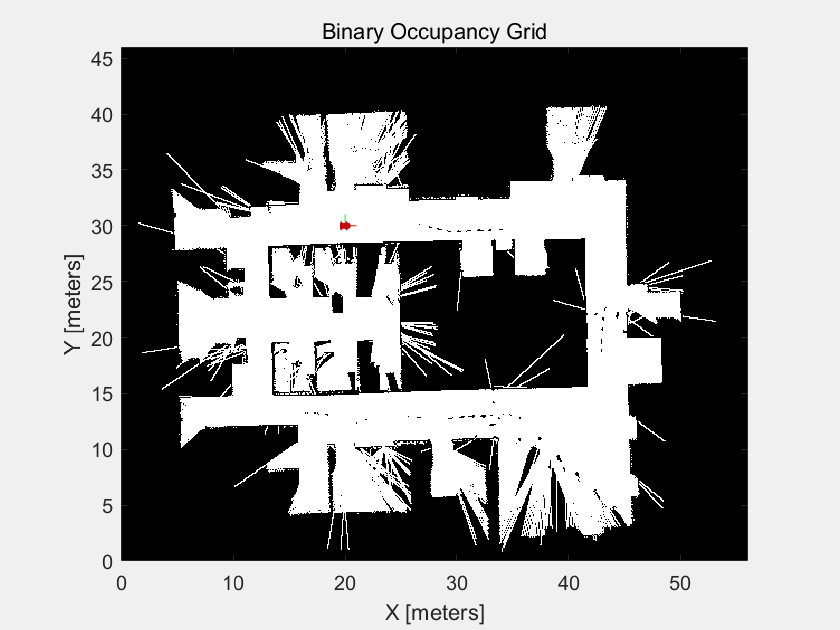

mapMatrix = office_area_map.occupancyMatrix > 0.5;
mapScale = 10;
initX = 20;
initY = 30;
initTheta = 0;
fig = figure("Name","office_area_map");
set(fig,"Visible","on");
ax = axes(fig);
show(binaryOccupancyMap(mapMatrix,mapScale),"Parent",ax);
hold on
plotTransforms([initX,initY,0],eul2quat([initTheta, 0, 0]),"MeshFilePath","groundvehicle.stl","View","2D");
light;
hold off

### Simulate

out = sim("exampleHelperAvoidObstaclesMobileRobot.slx");

### Visualize

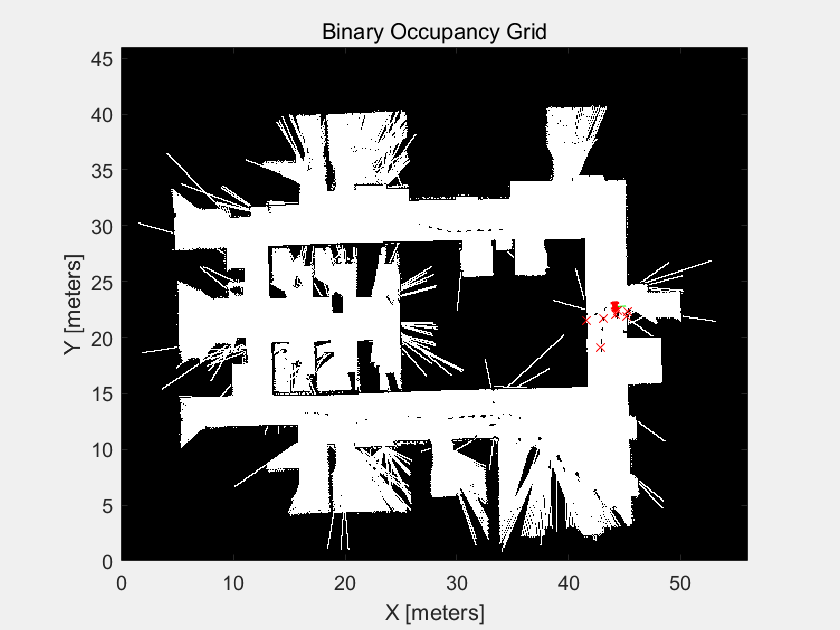

for i = 1:5:size(out.range,3)
    u = out.pose(i,:);
    r = out.range(:,:,i);
    exampleHelperAvoidObstaclesPosePlot(u,mapMatrix,mapScale,r,scanAngles,ax);
end

*Copyright 2019-2021 The MathWorks, Inc.*